We will operate on qtdb database sampled at 250Hz

[record,a,b,c,d,e] = rdann('mitdb/103','atr');
[sig, Fs, tm] = rdsamp('mitdb/103', 1);

fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = Gz;
H{1} = Hz;
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = temp;
end
for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h),'LineWidth',2);
    hold on
end
title 'Filter bank using algorithm a  trous at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])
ylabel '|Q_k(e^{j\omega})|'
set(gca,'FontSize',24)
legend 'Q1' 'Q2'  'Q3'  'Q4'  'Q5'

fsamp=pi;
fcuts=[pi/6+0.0,pi/6+0.1];
mags=[1,0];
devs=[0.05,0.01];
[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fsamp);
hh = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');
[h,q] = freqz( hh ,[1]);
plot(q*375/pi,abs(h),'LineWidth',2)
title 'Low pass filter required after upsampling'
xlabel 'Frequency (Hz)'
ylabel '|Q_k(e^{j\omega})|'
xlim([0,375])
xline(125)

ans =   ConstantLine with properties:

    InterceptAxis: 'x'
            Value: 125
            Color: [0.1500 0.1500 0.1500]
        LineStyle: '-'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


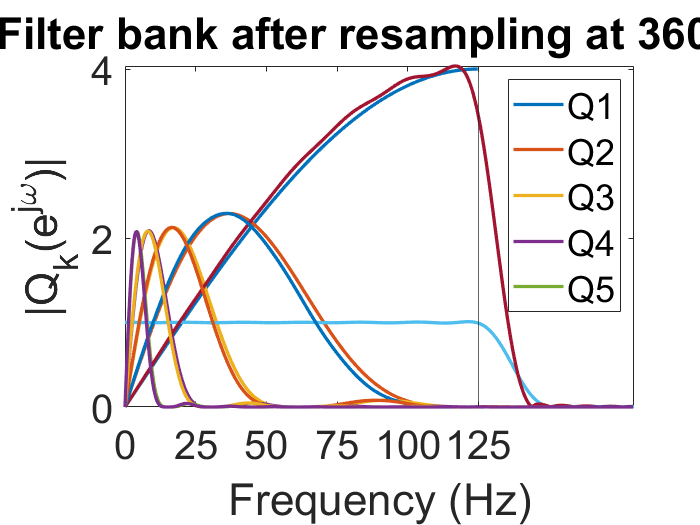

xticks([0,75,125,225,300,375])
set(gca,'FontSize',24)

for i = 1:(level)
    W{i}=2*upsample(W{i},3);
    W{i}=conv(W{i},hh);
    W{i}=downsample(W{i},2);
end
for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]); 
    q = q*180/pi;
    plot(q,abs(h),'LineWidth',2);
    hold on
end
title 'Filter bank after resampling at 360Hz'
xlabel 'Frequency (Hz)'
ylabel '|Q_k(e^{j\omega})|'
set(gca,'FontSize',24)
legend 'Q1' 'Q2'  'Q3'  'Q4'  'Q5'

xlim([0,180])
xticks([0,25,50,75,100,125,180])
t=tm;
xticks([0,25,50,75,100,125])

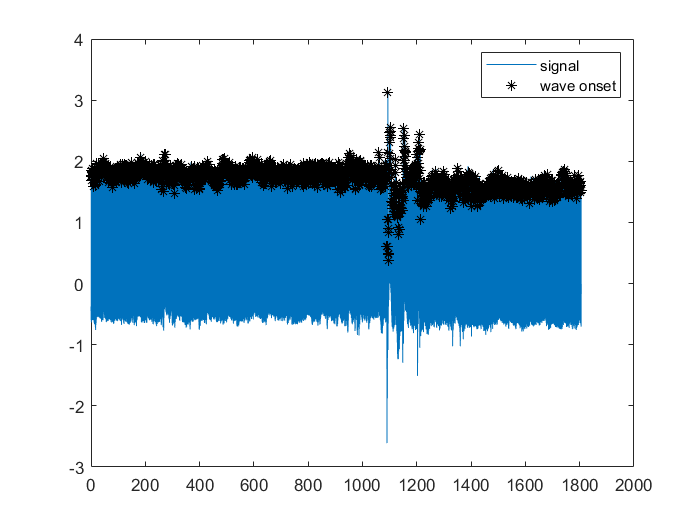

figure
plot(t,sig,t(record(find(a=='('))),sig(record(find(a=='('))),'r*');
hold on
plot(t(record(find(a==')'))),sig(record(find(a==')'))),'b*');
plot(t(record(find(a=='p'))),sig(record(find(a=='p'))),'g*');
plot(t(record(find(a=='t'))),sig(record(find(a=='t'))),'m*');
plot(t(record(find(a=='N'))),sig(record(find(a=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')

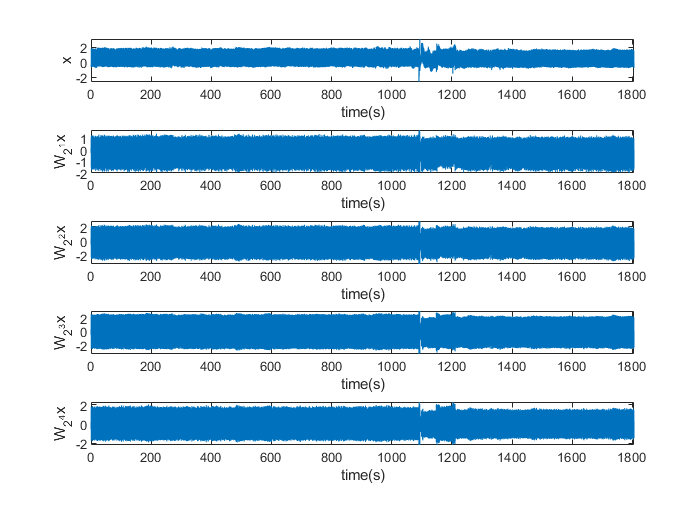

x=sig;
t=tm;
record_temp=record(find(a=='N'));
figure
w1 = filter(W{1},[1],x);
w2 = filter(W{2},[1],x);
w3 = filter(W{3},[1],x);
w4 = filter(W{4},[1],x);
delay1=round(median(grpdelay(W{1})));
delay2=round(median(grpdelay(W{2})));
delay3=round(median(grpdelay(W{3})));
delay4=round(median(grpdelay(W{4})));
x=x(1:end-delay4);
t=t(1:end-delay4);

w1(1:delay1)=[];
w1=w1(1:end-delay4+delay1);
w2(1:delay2)=[];
w2=w2(1:end-delay4+delay2);
w3(1:delay3)=[];
w3=w3(1:end-delay4+delay3);
w4(1:delay4)=[];
figure()
subplot(5,1,1)
plot(t,x)
axis tight
xlabel 'time(s)'
ylabel 'x'
subplot(5,1,2)
plot(t,w1)
xlabel 'time(s)'
axis tight
ylabel 'W_{2^1}x'
subplot(5,1,3)
plot(t,w2)
xlabel 'time(s)'
axis tight
ylabel 'W_{2^2}x'
subplot(5,1,4)
plot(t,w3)
axis tight
xlabel 'time(s)'
ylabel 'W_{2^3}x'
subplot(5,1,5)
plot(t,w4)
axis tight
xlabel 'time(s)'
ylabel 'W_{2^4}x'

Now we move to peak detection

length = 2^10;
steps=ceil(size(x,1)/length)

steps = 635

i = 10000

i = 20000

i = 30000

i = 40000

i = 50000

i = 60000

i = 70000

i = 80000

i = 90000

i = 100000

i = 110000

i = 120000

i = 130000

i = 140000

i = 150000

i = 160000

i = 170000

i = 180000

i = 190000

i = 200000

i = 210000

i = 220000

i = 230000

i = 240000

i = 250000

i = 260000

i = 270000

i = 280000

i = 290000

i = 300000

i = 310000

i = 320000

i = 330000

i = 340000

i = 350000

i = 360000

i = 370000

i = 380000

i = 390000

i = 400000

i = 410000

i = 420000

i = 430000

i = 440000

i = 450000

i = 460000

i = 470000

i = 480000

i = 490000

i = 500000

i = 510000

i = 520000

i = 530000

i = 540000

i = 550000

i = 560000

i = 570000

i = 580000

i = 590000

i = 600000

i = 610000

i = 620000

i = 630000

i = 640000

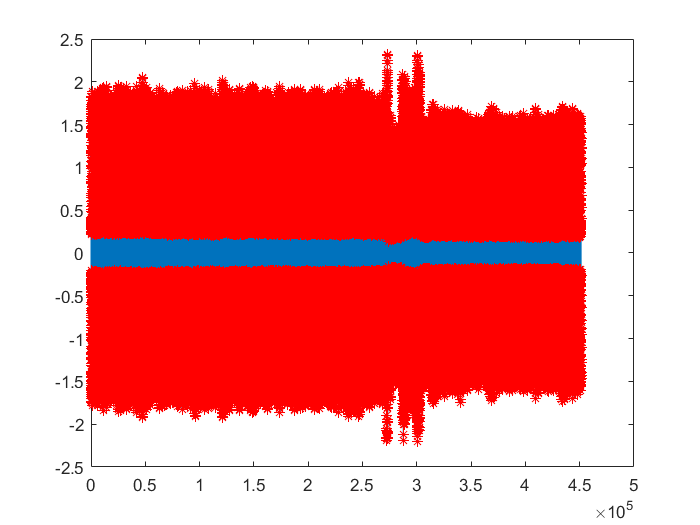

n4k=[];
n3k=[];
n2k=[];
n1k=[];
for i = 1:size(w4,1)
    e_4_QRS=rms(w4(max(i-length,1):min(size(w4,1),i+length)));
    if(abs(w4(i))>0.5*e_4_QRS)
        n4k=[n4k;i];
        e_3_QRS=rms(w3(max(i-length,1):min(size(w3,1),i+length)));
        set_3=abs(w3(max(1,i-5):min(i+5,size(w3,1))));
        if(max(set_3)>e_3_QRS)
            [val,max_pos]=max(set_3);
            n3k=[n3k;max(1,i-5)+max_pos-1];
            e_2_QRS=rms(w2(max(i-length,1):min(size(w2,1),i+length)));
            set_2=abs(w2(max(1,i-7):min(i+7,size(w2,1))));
            if(max(set_2)>e_2_QRS)
                [val,max_pos]=max(set_2);
                n2k=[n2k;max(1,i-7)+max_pos-1];  
                e_1_QRS=rms(w1(max(i-length,1):min(size(w1,1),i+length)));
                set_1=abs(w1(max(1,i-10):min(i+10,size(w1,1))));
                if(max(set_1)>e_1_QRS)
                    [val,max_pos]=max(set_1);
                    n1k=[n1k;max(1,i-10)+max_pos-1];   
                else
                    n1k=[n1k;0];
                end
            else
                n2k=[n2k;0];
                n1k=[n1k;0];
            end
        else
            n3k=[n3k;0];
            n2k=[n2k;0];
            n1k=[n1k;0];
        end
        
    end
    if(mod(i,10000)==0)
        i
    end
end

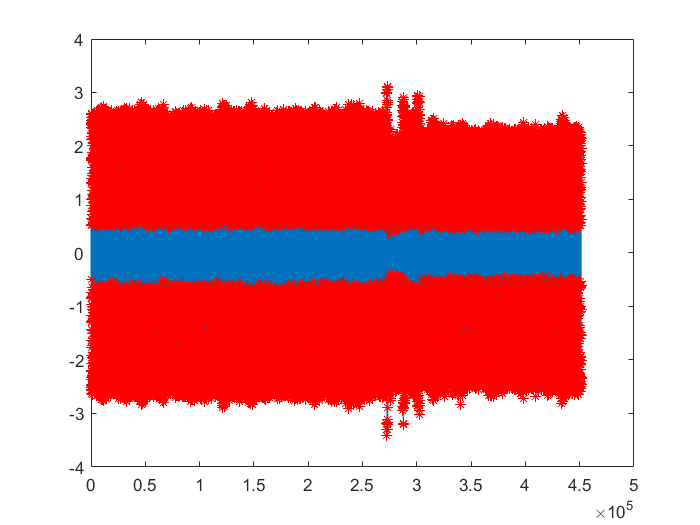

n3k=n3k.*(n1k~=0);
n3k(find(n3k==0))=[];

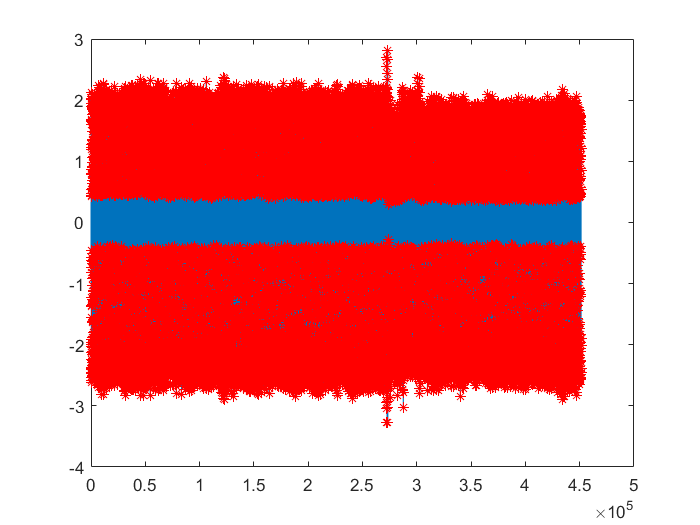

n2k=n2k.*(n1k~=0);
n2k(find(n2k==0))=[];figure
n1k(find(n1k==0))=[];

n1k=unique(n1k);

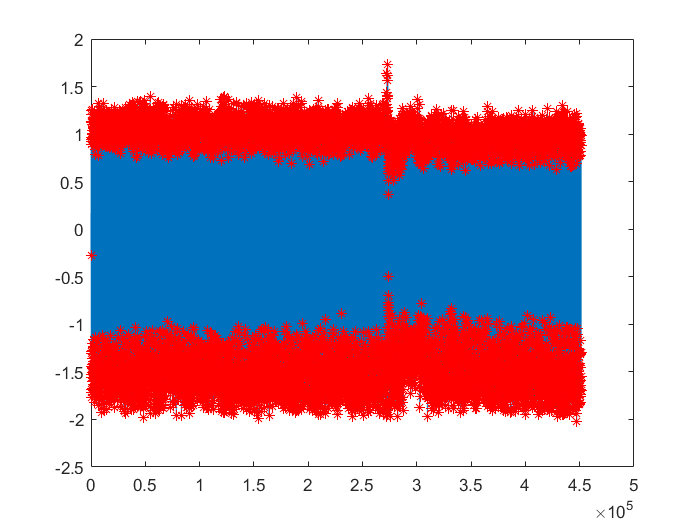

R=[];

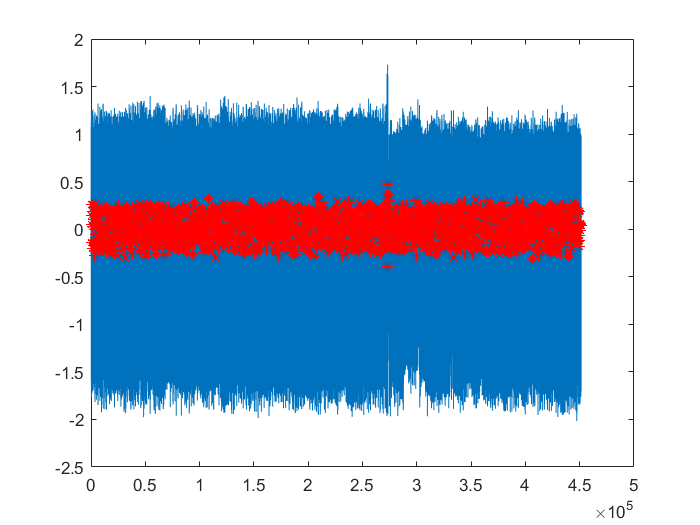

for i = 1:size(n1k)-1
    if(w1(n1k(i))*w1(n1k(i+1))<0 & (n1k(i+1)-n1k(i))<20)
       piece = abs(w1(n1k(i):n1k(i+1)));
       [junk,pos] = min(piece);
       R=[R;n1k(i)-1+pos];
    end
end
count=1;
while count<size(R,1)
    if((R(count+1)-R(count))<30)
            R(count+1)=[];
            count=count+1;
    else
        count=count+1;
    end
end
figure
plot(250*t,w1,250*t(R),w1(R),'r*')

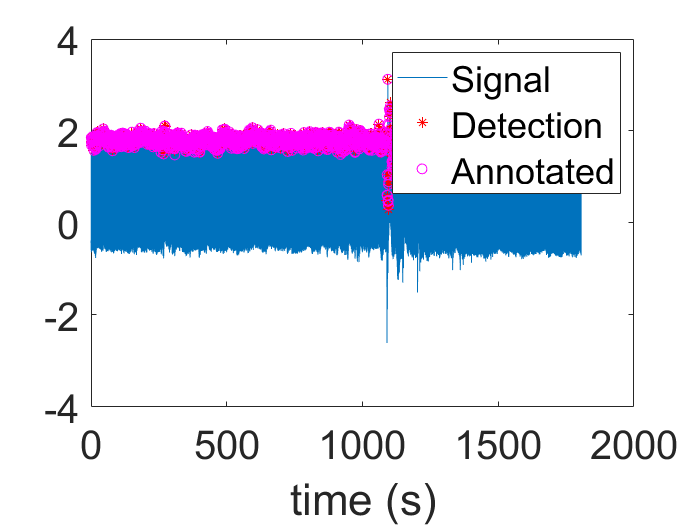

figure
plot(t,x,t(R),x(R),'r*',t(record_temp),x(record_temp),'mo')
xlabel 'time (s)'
legend 'Signal' 'Detection' 'Annotated'
set(gca,'FontSize',24)

true_positive=0;
false_negative=0;
for i = 1:size(record_temp,1)
    if(min(abs(record_temp(i)-R))<5)
        true_positive=true_positive+1;
    else
        false_negative=false_negative+1;
    end
end
false_positive=0;
for i = 1:size(R,1)
    if(min(abs(R(i)-record_temp))>4)
        false_positive=false_positive+1;
    end
end
true_positive

true_positive = 2082

false_negative

false_negative = 0

false_positive

false_positive = 2

se=true_positive/(true_positive+false_negative)*100

se = 100

p = 99.9040

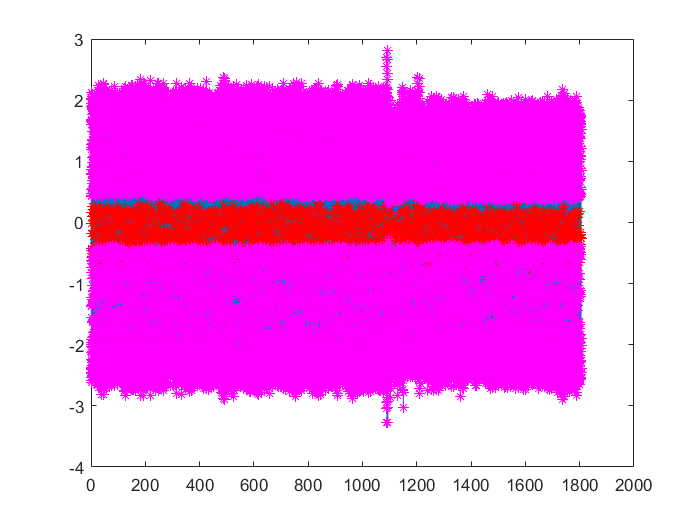

p=true_positive/(true_positive+false_positive)*100